# Gyakorlat 1

load carsmall;
%cars = importdata('carsmall.mat')

Mi az átlag, szórás és medián a Gyorsulásnál (Acceleration)?

mean(Acceleration)

ans = 15.0280

std(Acceleration)

ans = 3.3485

median(Acceleration)

ans = 15.1500

quantile(Acceleration,[0.25 0.75])

ans =    12.9000   17.3500


Az MPG (Miles Per Gallon) fogyasztás segítségével számoljuk ki az LPHKM (L/100km) változót, ha

- 1 gallon = 3.79 liter

- 1 mérföld = 1.61 km

Az elemenkénti operációk:

LPKHM = (1./((MPG*1.61)/3.79))*100

LPKHM =    13.0780
   15.6936
   13.0780
   14.7127
   13.8473
   15.6936
   16.8146
   16.8146
   16.8146
   15.6936


Kerekítsük 1 tizedesjegyre:

round(LPKHM,1)

ans =    13.1000
   15.7000
   13.1000
   14.7000
   13.8000
   15.7000
   16.8000
   16.8000
   16.8000
   15.7000


Melyik járműnek legnagyobb a fogyasztása? Használja a 'Model' karakter tömböt a típus megtalálásához.

m=max(LPKHM)

m = 26.1560

ind=find(LPKHM == m)

ind = 35

Model(ind, :)

ans = 'ih 1200d                         '

Hány kocsi fogyaszt többet 15 liternél? Mi az aránya ezeknek a kocsiknak?

sum(LPKHM>15)

ans = 20

mean(LPKHM>15)

ans = 0.2000

Vizsgálja meg a fogyasztást grafikusan hengerek száma (Cylinders) szerint boxplot segítségével.

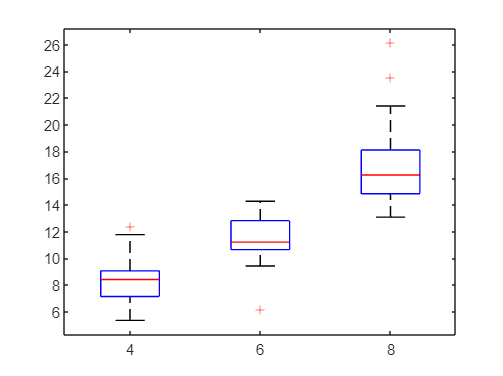

boxplot(LPKHM,Cylinders)

Ábrázolja a gyorsulás (Acceleration) értékeit hisztogrammon. Vizsgáljuk meg normalitás szempontjából.

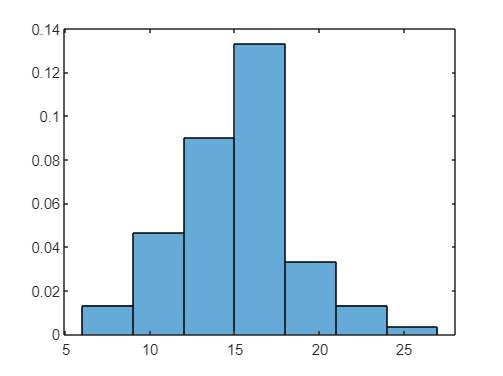


histogram(Acceleration,Normalization="pdf")

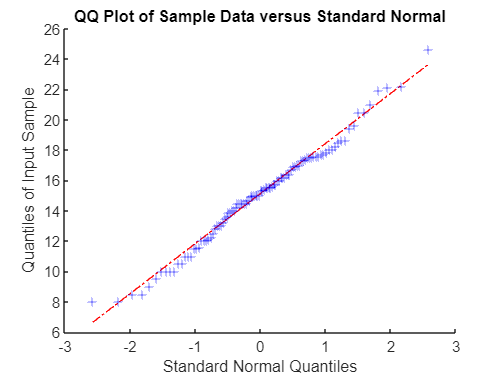


qqplot(Acceleration)

Rajzolja rá a sűrűségfüggvényt az ábrára! (**dfittool**)

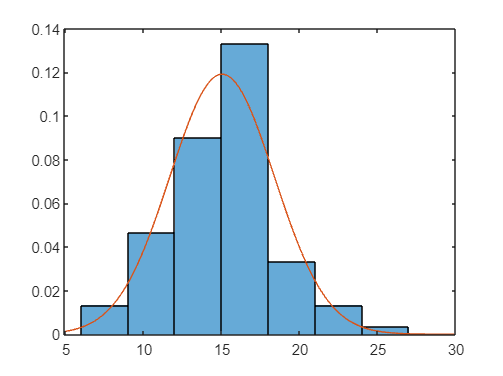

histogram(Acceleration,Normalization="pdf")
hold on
x= linspace(5,30);
m=mean(Acceleration); s=std(Acceleration);
y=normpdf(x,m,s);
plot(x,y)
hold off

Ábrázolja az empirikus eloszlásfüggvényt (ecdf) a súly (Weight) logaritmusára. Illesszünk egy megfelelőnek tűnő elméleti eloszlást az ábrára.

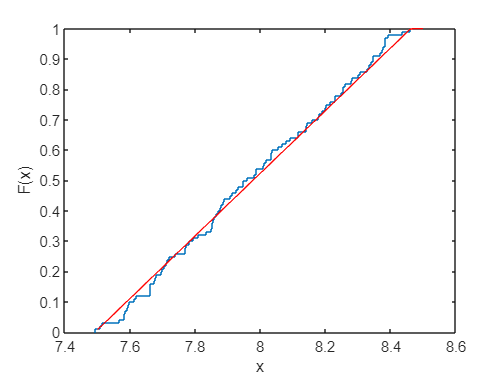

ecdf(log(Weight));
hold on 
[a b] = unifit(log(Weight));
x=linspace(7.5,8.5);
y=unifcdf(x,a,b);
plot(x,y,'r')


hold off

Az autók származási országáról (Origin) készítsen egy gyakorisági táblázatot.

t=tabulate(Origin)

t = 6×3 cell array
    {'USA'    }    {[69]}    {[69]}
    {'France' }    {[ 4]}    {[ 4]}
    {'Japan'  }    {[15]}    {[15]}
    {'Germany'}    {[ 9]}    {[ 9]}
    {'Sweden' }    {[ 2]}    {[ 2]}
    {'Italy'  }    {[ 1]}    {[ 1]}


t=cell2table(t)

t = 6×3 table
        t1         t2    t3
    ___________    __    __

    {'USA'    }    69    69
    {'France' }     4     4
    {'Japan'  }    15    15
    {'Germany'}     9     9
    {'Sweden' }     2     2
    {'Italy'  }     1     1


Ábrázoljuk oszlopdiagrammon.

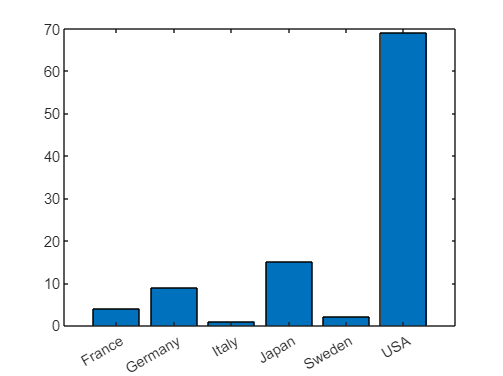

bar(categorical(t.t1),t.t2)

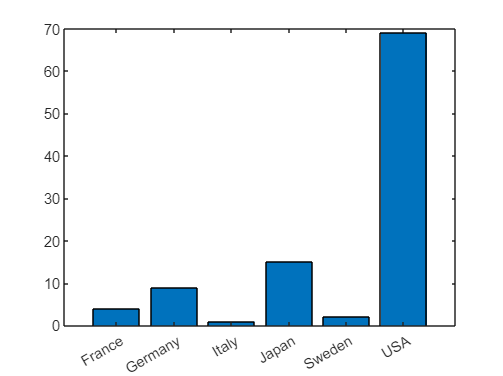

bar(categorical(t.t1),t.t2)